# Froude Krylov Equation

clear all
clc
t = input ('Enter Wave Period (s)...');
d = input ('Enter water depth (m)...');
g = 9.81;
L0 = 1.56 * t^2;
L0_old = L0;
    for i = 1:10000
        L_new = ((g*t^2)/(2*pi))*(tanh((2*pi)*d/L0_old));
        err = abs (L_new - L0_old);
            if err<=1e-6
                L = L_new;
            break;
            else
                L0_old = L_new;
            end
    end

## Wave Parameters

k = (2*pi/L);
n = 0.5 * (1 + ((2*k*d)/sinh(2*k*d)));
C0 = L0/t;
C = L/t;
Cg = n*C;
ks = sqrt (0.5 *(1/n)*(1/(C/C0)));
K = 1/cosh(k*d);
rho = 1020;
fprintf('L0 (m) = %5.2f\n',L0);

L0 (m) = 99.84


fprintf('d/L0 = %5.4f \n',d/L0);

d/L0 = 0.1002 


fprintf('d/L = %5.4f \n',d/L);

d/L = 0.1410 


fprintf('L (m) = %5.3f \n',L);

L (m) = 70.898 


fprintf('Wave Number (k) = %7.5f \n',k);

Wave Number (k) = 0.08862 


fprintf('2(pi)d/L = %5.3f \n',k*d);

2(pi)d/L = 0.886 


fprintf('tanh(2(pi)d/L = %5.4f \n',tanh(k*d));

tanh(2(pi)d/L = 0.7095 


fprintf('sinh(2(pi)d/L = %5.3f \n',sinh(k*d));

sinh(2(pi)d/L = 1.007 


fprintf('cosh(2(pi)d/L = %5.3f \n',cosh(k*d));

cosh(2(pi)d/L = 1.419 


fprintf('Shoaling Coefficient (H/H0) = %5.4f \n',ks);

Shoaling Coefficient (H/H0) = 0.9323 


fprintf('K = %5.3f \n',K);

K = 0.705 


fprintf('4(pi)d/L)=%5.3f \n',4*pi*(d/L));

4(pi)d/L)=1.772 


fprintf('sinh(4(pi)d/L)=%5.3f \n',sinh(2*k*d));

sinh(4(pi)d/L)=2.858 


fprintf('cosh(4(pi)d/L)=%5.3f \n',cosh(2*k*d));

cosh(4(pi)d/L)=3.028 


fprintf('n = %5.4f \n',n);

n = 0.8101 


fprintf('Cg/C0 = %5.4f \n',Cg/C0);

Cg/C0 = 0.5753 


fprintf('Celerity (m/s) = %5.3f \n',C);

Celerity (m/s) = 8.862 


fprintf('Group Celerity (m/s) = %5.3f \n',Cg);

Group Celerity (m/s) = 7.180 


D = input ('Enter the diameter of the pile (m)...');
H = input ('Enter the wave height (m)...');
h = input ('Enter the height of the pile (m)...');
fprintf ('h/d value is %5.2f \n',h/d); %% if h/d <0.6 Ch, Cv and Co can be calculated, if 0.3 < h/D < 2.3 for Ch and Cv only, 0.6 < h/D < 2.3 for Co only

h/d value is  0.40 


fprintf ('H/D ratio is %5.2f \n',H/D); %% H/D should be > 1 for both drag and inertia

H/D ratio is  0.12 


fprintf ('D/L ratio is %5.4f \n',D/L); %% D/L should be < 0.2 for both drag and inertia

D/L ratio is 0.0846 


## Submerged Cylinder Total Forces and Moments

Ch = 1+((0.75*(h/D)^(1/3))*(1-(2.96*(D/L)^2)));
che = pi * h/L;
if che < 1
    Cv = 1 + (7.3*(D/L)^2*(h/D)); %% for pi*h/L < 1
else
    Cv = 1 + (1.57*(D/L)); %% for pi*h/L>1
end
Co = 1.9 - (1.1 * (D/L));
fprintf('Ch = %5.3f',Ch);

Ch = 1.641

fprintf('Cv = %5.3f',Cv);

Cv = 1.035

fprintf('Co = %5.3f',Co);

Co = 1.807

omega = (2*pi)/t;
ti = linspace(4,12,100);
A = 2 * rho * g * (D/2) * H * ((sinh(k*h))/(k*cosh(k*d)))*sin(k*(D/2));
B = 2 * rho * g * (D/2) * H * ((cosh(k*h)-1)/(k*cosh(k*d)))* sin(k*(D/2));
for i = 1:100
    F_fx(i) = Ch * A * sin(omega*ti(i));
    F_fz(i) = Cv * B * cos(omega*ti(i));
end
fprintf ('A value is %5.2f \n',A);

A value is 34050.93 


fprintf ('B value is %5.2f \n',B);

B value is 5972.94 


## plots

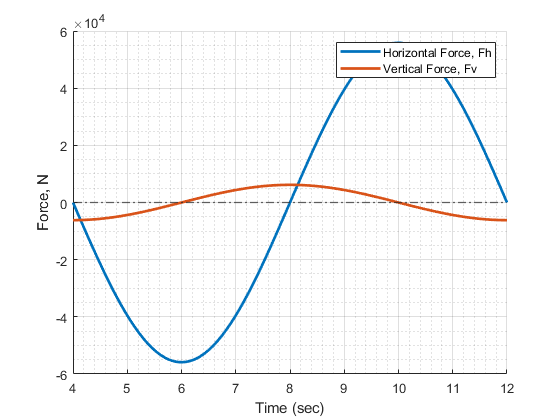

hold on
plot (ti,F_fx,"LineWidth",2);
plot (ti,F_fz,"LineWidth",2);
yline(0,"Linestyle",'-.',"Linewidth",1);
xlabel 'Time (sec)'
ylabel 'Force, N'
legend ('Horizontal Force, Fh','Vertical Force, Fv');
grid on
grid minor
hold off

## Moments

P = 2 * rho * g * (D/2) * (H/k^2) * (sin(k*(D/2))/cosh(k*d))*(1+(k*h*sinh(k*h))-(cosh(k*h)));
Q = 2 * rho * g * (D/2) * (H/k^2) * ((cosh(k*h)-1)/cosh(k*d))*(sin(k*(D/2))-(k*(D/2)*cosh(k*(D/2))));
for i = 1:100
    Mh(i) = 2 * rho * g * (D/2) * (H/k^2) * (sin(k*(D/2))/cosh(k*d))*(1+(k*h*sinh(k*h))-(cosh(k*h)))*sin(omega*ti(i));
    Mv(i) = 2 * rho * g * (D/2) * (H/k^2) * ((cosh(k*h)-1)/cosh(k*d))*(sin(k*(D/2))-(k*(D/2)*cosh(k*(D/2))))*sin(omega*ti(i));
    Mf(i) = Mh(i) + Mv(i);
    Mo(i) = Co * Mf(i);
end
fprintf ('P value is %5.2f \n',P);

P value is 68806.16 


fprintf ('Q value is %5.2f \n',Q);

Q value is -3225.14 


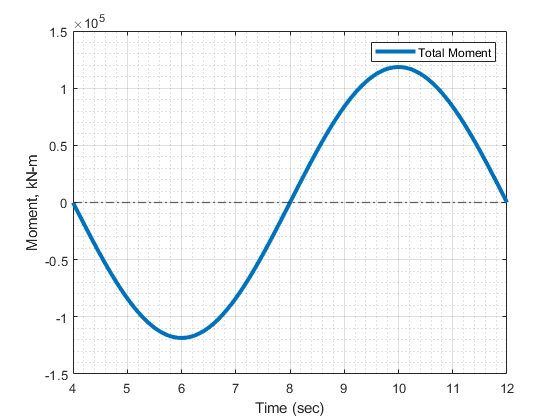

plot (ti,Mo,"LineWidth",3);
yline(0,"Linestyle",'-.',"Linewidth",1);
xlabel 'Time (sec)'
ylabel 'Moment, kN-m'
legend ('Total Moment');
grid on
grid minor